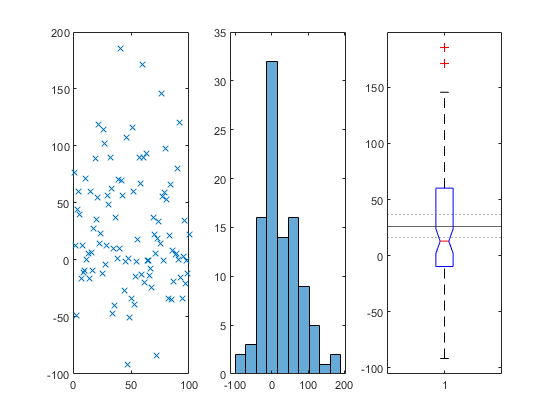

clear all;
close all;

fin = fopen('sgbdold.dat','r');
data_old = fscanf(fin,'%f');
fclose(fin);
fin = fopen('sgbdnew.dat','r');
data_new = fscanf(fin,"%f");
fclose(fin);
diff = data_old - data_new;
x = 1:length(diff);

sample_mean = mean(diff);
sample_stddev = std(diff);
eta = 1.96;
bound = eta*sample_stddev/sqrt(length(diff));
ub = sample_mean + bound;
lb = sample_mean - bound;

subplot(1,3,1);
plot(diff,'x');
xticks([0 50 100]);
ylim([-100 200]);
yticks([-100 -50 0 50 100 150 200]);
subplot(1,3,2);
histogram(diff,'NumBins',10);
xticks([-100 0 100 200]);
subplot(1,3,3);
boxplot(diff,'Notch','on','Labels','1');
hold on
yline(sample_mean);
hold on
yline(ub,':');
hold on
yline(lb,':');
hold off